# Homework 1 - CEWA 573

**Data downloaded from the CDIP website (a wonderful resource for wave data) are provided as text files.**

## **Question 1**

#### Read the data from the Station Papa text file into MATLAB, and create a datenum time vector, using the following code:

#### `[Year,Mo,Day,Hr,Min,Hs,Tp,Dp,Ta,Temp] = textread(’PAPA_Feb2016.txt’,’%f %f %f %f %f %f %f %f %f %f’,’headerlines’,2);`

#### `t = datenum(Year,Mo,Day,Hr,Min,zeros(size(Year)) );`

#### Plot the wave height (Hs), peak wave period (Tp) and peak wave direction (Dp).

Datenum time vector:

[Year,Mo,Day,Hr,Min,Hs,Tp,Dp,Ta,Temp] = textread('HW1_PAPA_Feb2016.txt',...
'%f %f %f %f %f %f %f %f %f %f','headerlines',2);
t = datenum(Year,Mo,Day,Hr,Min,zeros(size(Year)) );
t_new = (t - t(1,1)) + 1; % start from zero

Plot of the wave height (Hs), peak wave period (Tp) and peak wave direction (Dp).

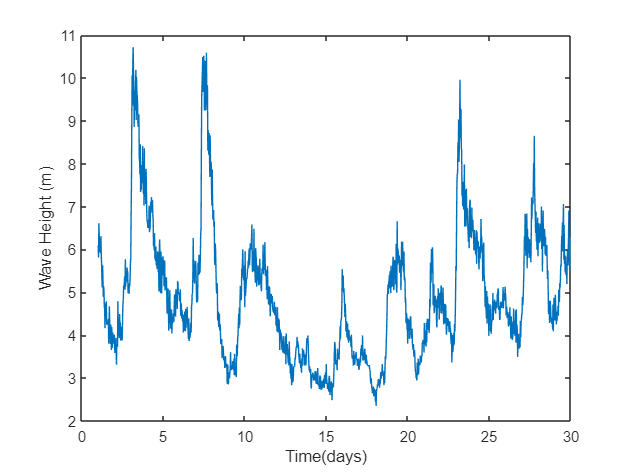

plot(t_new, Hs)
xlabel('Time(days)')
ylabel('Wave Height (m)')

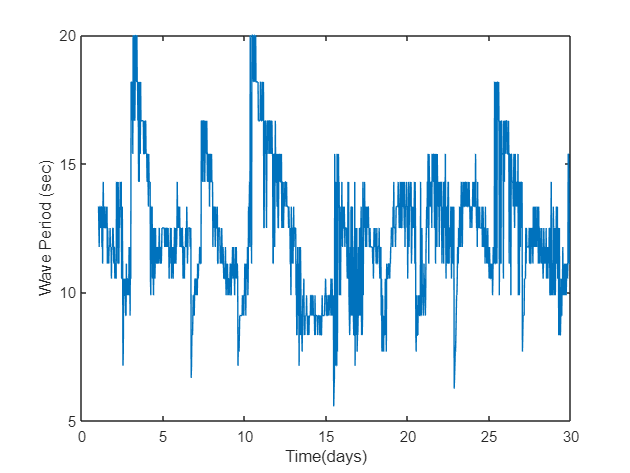

plot(t_new, Tp)
xlabel('Time(days)')
ylabel('Wave Period (sec)')

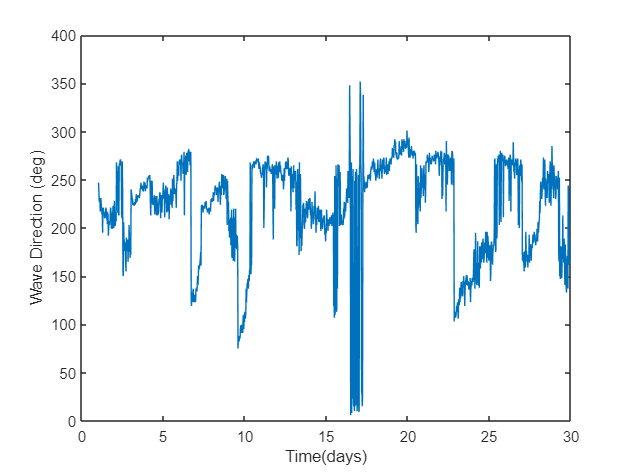

plot(t_new, Dp)
xlabel('Time(days)')
ylabel('Wave Direction (deg)')

## Question 2

#### On February 10th, the wave buoy at P measured wave periods near 20 s. These long waves decay over the subsequent few days, while wave heights remain relatively similar. What physical process might cause this effect?

High winds in the area might be the cause for that phenomenon.

## Question 3

#### Make and plot a time series of energy flux using the wave height and peak period data. Depth at station Papa is 4200 m. Which storms were the most energetic? How might you distinguish local, and non local wave events?

Time series of energy flux using the wave height and peak period data. 

Depth = 4200; % (m) at Papa
% Find wave length, L
DecPlaces =2; % Decimal places
InitApprox = 100; % Initial appproximation (m)
signal_Lenght = size(Hs, 1); g = 9.81; rho = 1305;
% syms L; 
% Wave_Length = zeros(signal_Lenght, 1);
% for ii = 1:signal_Lenght
%     f=(g*Tp(ii,1)^2/(2*pi))*tanh(2*pi*Depth/L)-L; %Enter the Function here
%     [Wave_Length(ii, 1), ~] = NewtonRaphson(f, L, DecPlaces, InitApprox);
% end

Now, we find the wave parameters

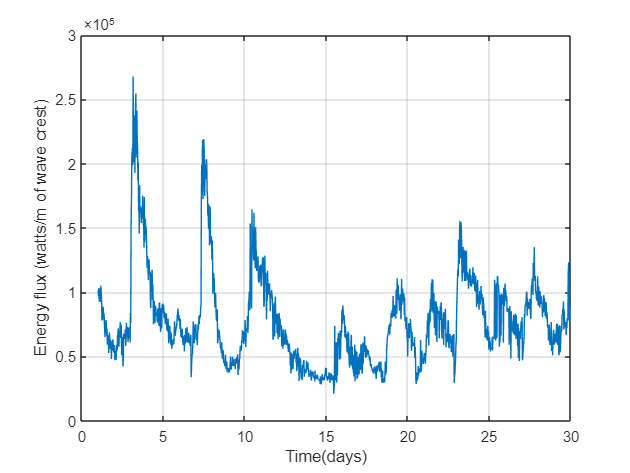

Relative_Depth = Depth./Wave_Length; % d/L
k = (2*pi)./Wave_Length; % wave number
Group_Vel_Param = (0.5).*(1 + (2.*k.*Depth)./(sinh(2.*k.*Depth)));
Wave_velocity = Wave_Length./Tp; % m/s
Group_velocity = Group_Vel_Param.*Wave_velocity; % m/s
Energy_Density = (1/8).*rho.*g.*Hs; % joules/m2
Energy_Flux = Energy_Density.*Group_velocity; % watts/m of wave crest

% Plot energy flux
plot(t_new, Energy_Flux)
xlabel('Time(days)')
ylabel('Energy flux (watts/m of wave crest)')
grid on

The most energetic storms started on February 3, 7, and 10.

In order to distinguish between local and non-local wave effects, one might compare de wave direction vs. wind direction. The agreement between wave direction and wind direction indicates the presence of sea waves (generated locally by winds); whereas, the disagreement of this to parameters indicate the presence of swell wave, which travel beyond the area in which they were generated.

## Question 4

#### Now load in the Umpqua data. Plot a time series of the peak wave period from both buoys on the same axis. What accounts for the similarities or differences in the two time series?

Datenum time vector:

[DataUmpqua.Year,DataUmpqua.Mo,DataUmpqua.Day,DataUmpqua.Hr,DataUmpqua.Min,DataUmpqua.Hs,...
    DataUmpqua.Tp,DataUmpqua.Dp,DataUmpqua.Ta,DataUmpqua.Temp] = textread('HW1_UMPQUA_Feb2016.txt',...
'%f %f %f %f %f %f %f %f %f %f','headerlines',2);
DataUmpqua.t = datenum(DataUmpqua.Year,DataUmpqua.Mo,DataUmpqua.Day,DataUmpqua.Hr,...
    DataUmpqua.Min,zeros(size(DataUmpqua.Year)) );
DataUmpqua.t_new = (DataUmpqua.t - DataUmpqua.t(1,1)) + 1; % start from zero

Plotting peak wave period from both buoys on the same axis

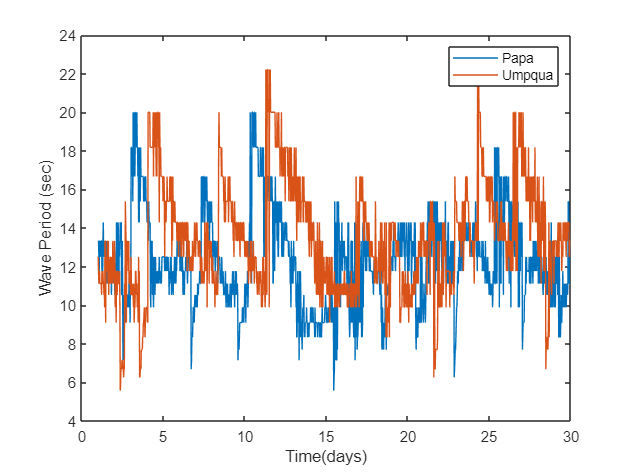

plot(t_new, Tp)
hold on
plot(DataUmpqua.t_new, DataUmpqua.Tp)
xlabel('Time(days)')
ylabel('Wave Period (sec)')
legend('Papa', 'Umpqua')

We can observe that the signals look very similar but are shifted by around 1 day. The similiraties can be atributted to events that were very energetic as to allow waves from Papa to reach Umpqua. The larger period of waves in Umpqua suggest that energy has been lost on the wave's path.

The differences can be attributed to events that did not have enough energy to transport energy via the waves; therefore, waves generated in either place could not reach the other place.